# ISET3d: Assets

The scene **assets** are the collection of objects and lights that are used in a PBRT scene.  The assets are stored in the recipe slot: **thisR.assets,** which is a Matlab **tree** class.  Trees are a natural way to combine the description of objects with the transforms applied to those objects.  The nodes in the thisR.assets tree represent the assets (objects) and the transforms needed to render the assets.

The tree representation is simple.  It is a cell array of nodes (Node), each with a unique name, and a vector of integers (Parent) that specifies the identity of the parent node for every node.  

The @tree class has many methods for, say, visualizing the tree, grafting onto the tree, chopping off a branch, and so forth. 

The asset tree can be thought of as the branches and leaves.  Often, the  **branches**  represent transformations that control the position, orientation, and size of the objects.  These transformations are applied to all the objects below the branch. The **leaves** define the shape and material of the object.  In some cases, a branch may be an object and beneath it may be additional branches and leaves describing parts of that object.

This tutorial illustrates a few of the ways to control the properties and transforms of objects in an asset tree.  

The software interface is intended to make controlling the objects close to writing simple sentences.  The programming  consists of **set** and **get** commands that apply to the nodes of the tree. These have the form 

or

ISET3d Methods illustrated in this script are

**See also **

    t_assetsMotion.m, t_materials.m

## The simple scene

This simple scene has about 25 objects and is useful for demonstrating ISET3d programming.  Here is a low resolution rendering of the scene.  

ieInit;
if ~piDockerExists, piDockerConfig; end
thisR = piRecipeDefault('scene name', 'SimpleScene');

Read 1 materials.
Read 1 textures.
***Scene parsed.


We set a low resolution for speed.

thisR.set('film resolution',[200 150]);
thisR.set('rays per pixel',32);
thisR.set('fov',45);
thisR.set('nbounces',5);

## Render the scene

piWrite(thisR);

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt


scene = piRender(thisR, 'render type', 'radiance');

Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene":"/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  3.0 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.


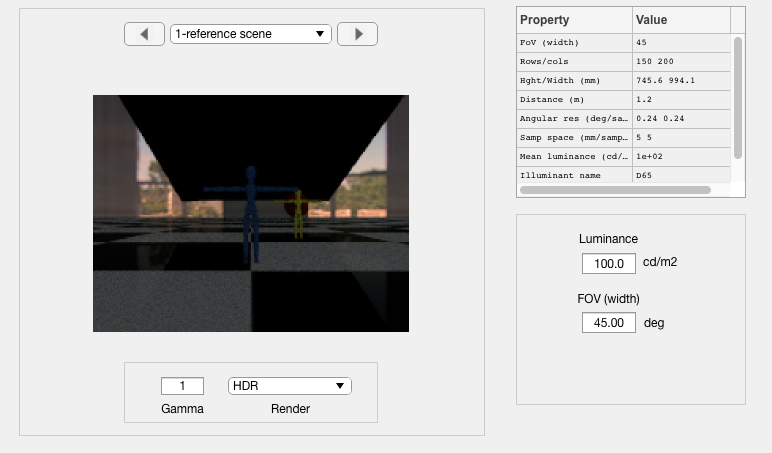

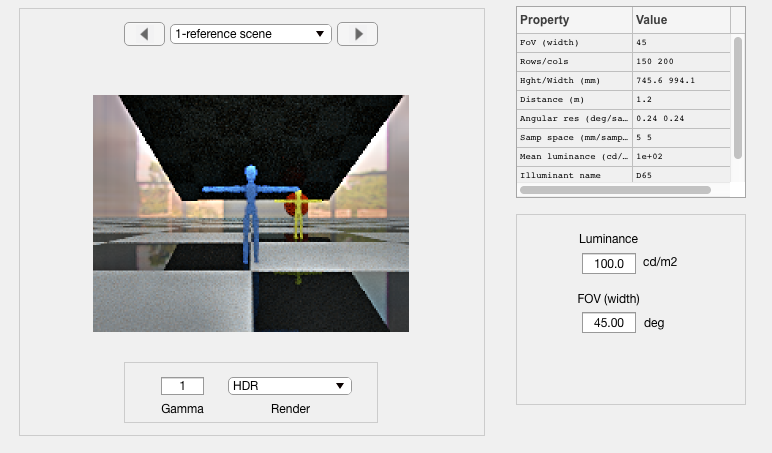

scene = sceneSet(scene, 'name', 'reference scene');
sceneWindow(scene);
sceneSet(scene, 'render flag', 'hdr');

## The asset tree

The recipe **thisR** contains the **assets** tree.  This is a simple tree with only a few assets.

thisR.assets

ans =   tree with properties:

      Node: {26×1 cell}
    Parent: [26×1 double]


You can display the tree data in several ways, using the show command.  By default, calling thisR.show opens a window to the top level of the tree. By clicking on the black triangles, you can explore different depths of the tree.

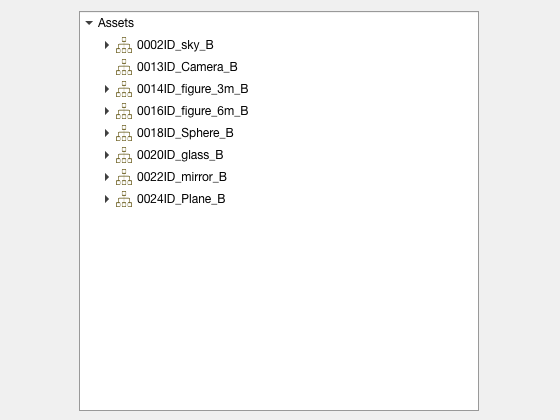

assetTree = thisR.assets.show;

You can also print the asset tree structure in the command window

thisR.assets.print;

                                                                                                         0001ID_root                                                                                                         
                                                  +----------------------------------------------------------++----------------+----------------+----------------+----------------+----------------+----------------+        
                                                  |                                                           |                |                |                |                |                |                |        
                                            0002ID_sky_B                                               0013ID_C..era_B  0014ID_f.._3m_B  0016ID_f.._6m_B  0018ID_S..ere_B  0020ID_g..ass_B  0022ID_m..ror_B  0024ID_P..ane_B 
                                                                                                                

You can also visualize the positions of the assets this way

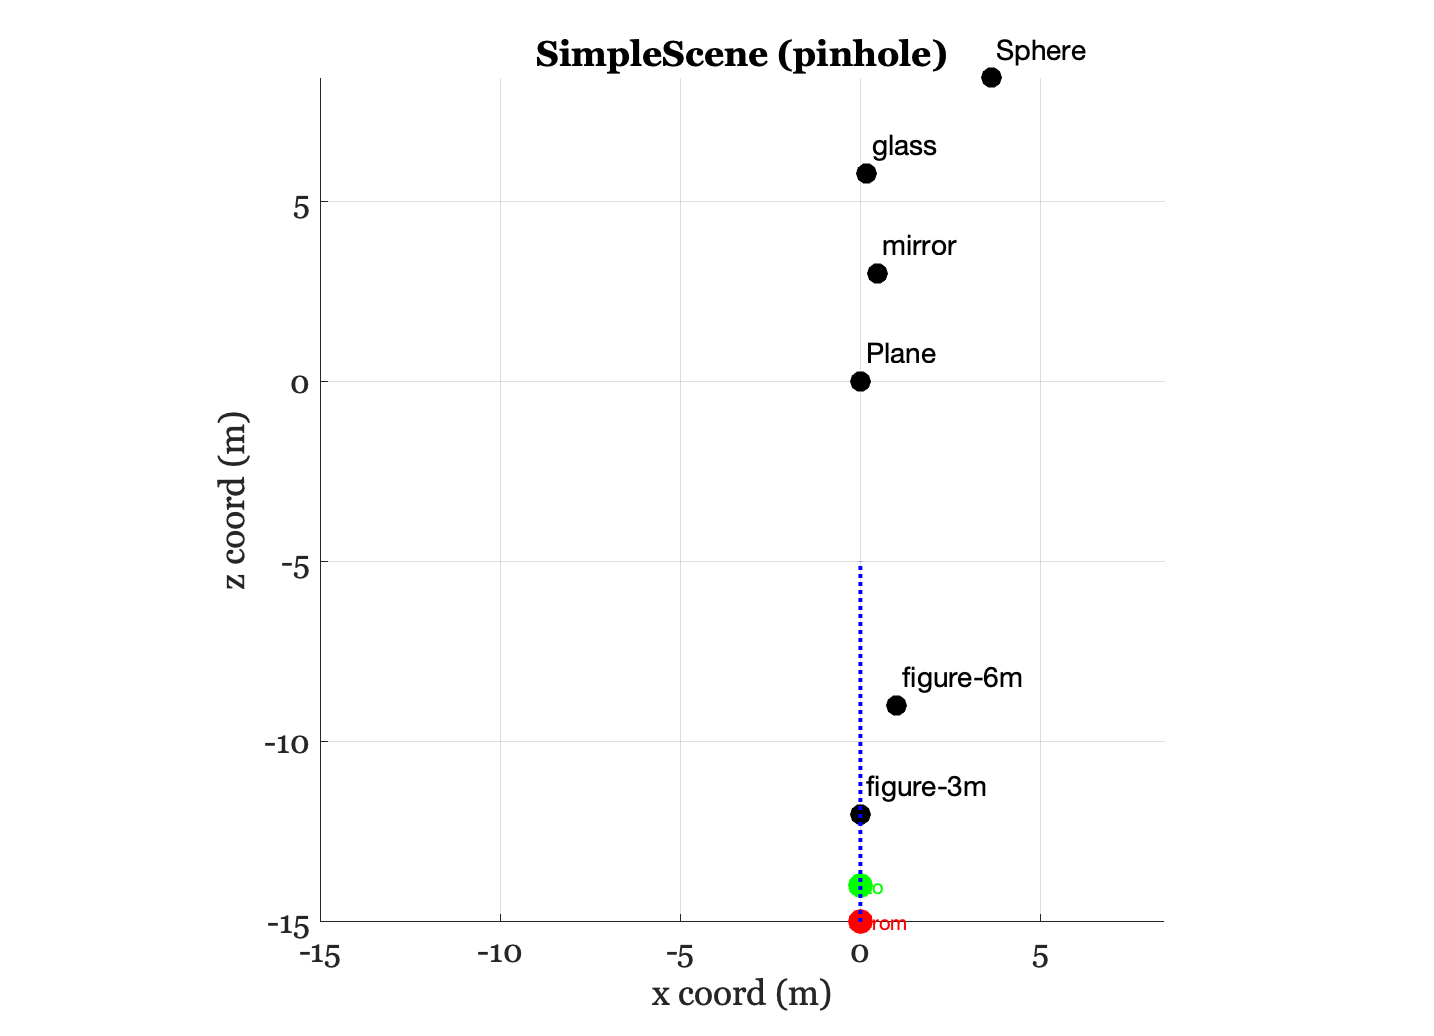

piAssetGeometry(thisR);

## Tree methods 

There are many tree methods that can be applied to the assets.  Here are a few examples.

## Get an asset node

You can get a node by name.  The asset names are formatted as **XXXXID_AssetName_Type**.  You do not need to include the ID when requesting the asset, just its name and type (though you can).  The exception is if you have two different nodes with the same name: Then you need to specify the ID.

thisR.get('node','sky_B')

ans = struct with fields:
               type: 'branch'
               name: '0002ID_sky_B'
               size: [1×1 struct]
              scale: {[1 1 1]}
        translation: {[0 0 0]}
           rotation: {[4×3 double]}
    concattransform: []
             motion: []
         transorder: 'TRS'


To return the node ID you can use this

thisR.get('node id','sky_B')

ans = 2

The parent of the asset is:

thisR.get('node parent','sky_B')

ans = '0001ID_root'

You can use the node number to get the asset with this command

thisR.assets.get(2)

ans = struct with fields:
               type: 'branch'
               name: '0002ID_sky_B'
               size: [1×1 struct]
              scale: {[1 1 1]}
        translation: {[0 0 0]}
           rotation: {[4×3 double]}
    concattransform: []
             motion: []
         transorder: 'TRS'


When the node of the tree is a transformation, you can get the transformation parameters this way.  For example, to read the translation parameter use

thisR.get('node','sky_B','translation')

ans = 1×1 cell array
    {1×3 double}


thisR.get('node','sky_B','scale')

ans = 1×1 cell array
    {1×3 double}


thisR.get('node','001_figure_3m_O','world position')

ans =          0    0.5000  -12.0281


## Rotate the blue man

The implementation is designed to simplfy changing the position, orientation or other properties of an object.  For example, the blue man is stored in the node named '001_figure_3m_O'. We rotate the asset with this command

nodeName = '001_figure_3m_O'; 
thisR.set('node', nodeName, 'rotate', [0, 0, 45]);

## Write and render

piWrite(thisR);

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt


scene = piRender(thisR, 'render type', 'radiance');

Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene":"/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  3.4 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.


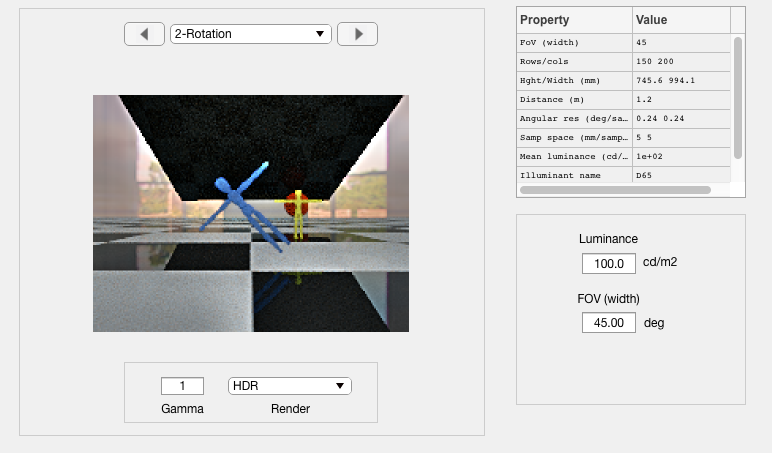

scene = sceneSet(scene, 'name', 'Rotation');
sceneWindow(scene);

## Translate

The yellow man's position in the world can be translated this way.

nodeName = '001_figure_6m_O';
thisR.set('node', nodeName, 'translate', [0, 0, -2]);
piWrite(thisR);

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt


scene = piRender(thisR, 'render type', 'radiance');

Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene":"/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  3.3 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.


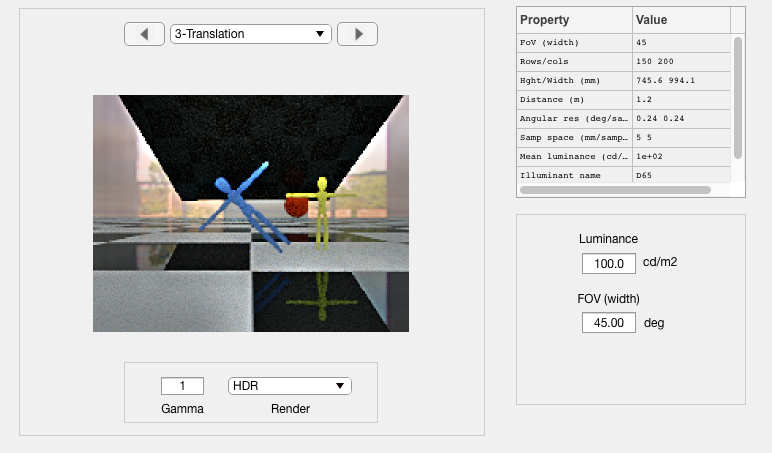

scene = sceneSet(scene, 'name', 'Translation');
sceneWindow(scene);

## Scale

We increase the size of the yellow man

nodeName = '001_figure_6m_O';
thisR.set('node', nodeName, 'scale', 1.3);
piWrite(thisR);

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt


scene = piRender(thisR, 'render type', 'radiance');

Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene":"/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  3.3 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.


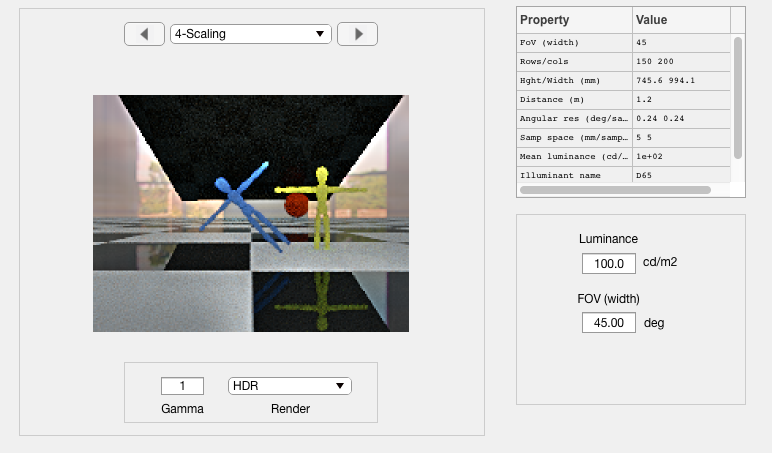

scene = sceneSet(scene, 'name', 'Scaling');
sceneWindow(scene);

## Add an object

We have test charts and other assets stored as recipes that can be merged into a scene.  Here is a color test chart that we can merge into the Simple Scene.

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene":"/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  3.8 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.


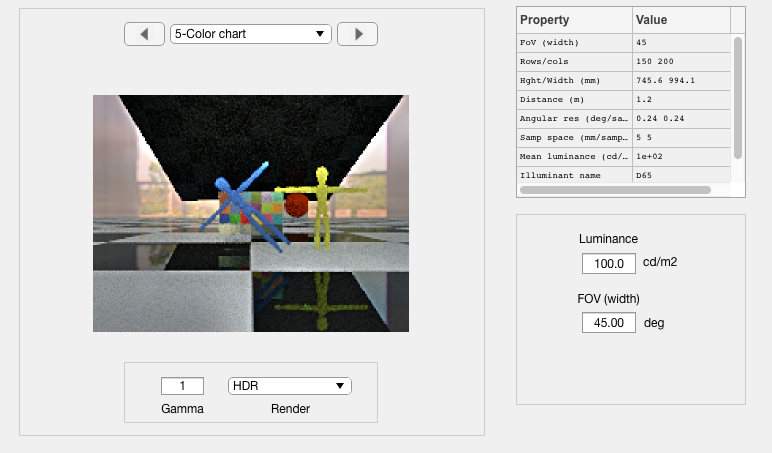

mcc = piAssetLoad('macbeth');
piRecipeMerge(thisR,mcc.thisR,'node name',mcc.mergeNode);
s = thisR.get('asset',mcc.mergeNode,'scale');

nodeName = '001_figure_3m_O';
bPos = thisR.get('asset',nodeName,'world position');

thisR.set('asset',mcc.mergeNode,'world position',bPos + [0 0 2]);
piWRS(thisR,'name','Color chart');

## Delete an object

Let's remove the blue man so we can see the color chart more clearly.

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene":"/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  3.1 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.


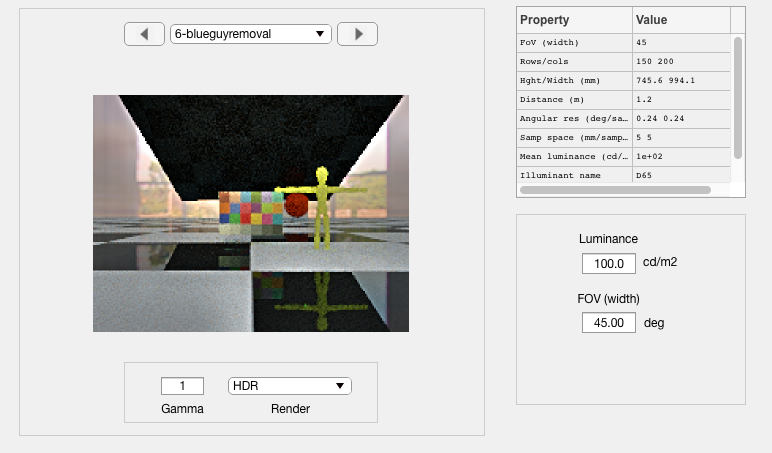

thisNode = '001_figure_3m_O'; 
thisR.set('node',thisNode,'delete'); 
scene = piWRS(thisR,'name','blueguyremoval');